%% PHÂN TÍCH ĐA THAM SỐ: TỐI ƯU HÓA H VÀ R CHO KEYENCE FU-40S & SICK KT5W
clear; clc;

% 1. KHAI BÁO CÁC TRƯỜNG HỢP VÀ NHẬP LỰA CHỌN
TestCases = [
    20, 30;   % TH1: H thấp, R nhỏ
    25, 35;   % TH2: H trung bình, R trung bình (Khuyến nghị)
    30, 35;   % TH3: H cao, R trung bình
    60, 60    % TH4: H cao, R lớn
];

fprintf('Danh sách các trường hợp kiểm tra [H_mm, R_mm]:\n');

Danh sách các trường hợp kiểm tra [H_mm, R_mm]:


for i = 1:size(TestCases, 1)
    fprintf('  [%d] H = %d mm, R = %d mm\n', i, TestCases(i,1), TestCases(i,2));
end

  [1] H = 20 mm, R = 30 mm
  [2] H = 25 mm, R = 35 mm
  [3] H = 30 mm, R = 35 mm
  [4] H = 60 mm, R = 60 mm



% Yêu cầu người dùng nhập trường hợp muốn xem
case_idx = input('Nhập số thứ tự trường hợp bạn muốn hiển thị (1-4): ');

% Bắt lỗi nếu nhập sai
if isempty(case_idx) || case_idx < 1 || case_idx > size(TestCases, 1)
    fprintf('Lựa chọn không hợp lệ! Hệ thống tự động chọn Trường hợp 1.\n');
    case_idx = 1;
end

H = TestCases(case_idx, 1);
R = TestCases(case_idx, 2);

% 2. THÔNG SỐ CỐ ĐỊNH CỦA ĐĨA VÀ CẢM BIẾN
num_segments = 6;        
d0_mm = 2.2;             % Lõi sợi quang Keyence
alpha = 6 * (pi/180);    % Góc phân kỳ 12 độ (Keyence)
D_spot_sick = 2;         % Vết sáng SICK luôn cố định 1.2mm dọc
t_keyence = 300 / 1e6;   % Giới hạn Keyence tính bằng giây (0.0003 s)
t_sick = 50 / 1e6;       % Giới hạn SICK tính bằng giây (0.00005 s)

% Định nghĩa dải tốc độ (RPM) làm gốc
rpm_range = linspace(50, 6000, 1000); 

% 3. CHUẨN BỊ ĐỒ THỊ
figure('Color', 'w', 'Name', sprintf('Parametric Analysis - TH%d', case_idx));
hold on; grid on;

% 4. TÍNH TOÁN VÀ VẼ CHO TRƯỜNG HỢP ĐÃ CHỌN
fprintf('\n--- KẾT QUẢ KIỂM TRA QUANG HỌC ---\n');


--- KẾT QUẢ KIỂM TRA QUANG HỌC ---



% --- Tính toán quang học chung ---
S_raw = (2 * pi * R) / num_segments;

% --- KEYENCE FU-40S ---
D_spot_k = d0_mm + 2 * H * tan(alpha);
S_eff_k = S_raw - D_spot_k;

% --- SICK KT5W ---
S_eff_s = S_raw - D_spot_sick;

fprintf('TH%d [H=%d, R=%d]: S_raw = %.2f | Keyence S_eff = %.2f | SICK S_eff = %.2f\n', ...
    case_idx, H, R, S_raw, S_eff_k, S_eff_s);

TH4 [H=60, R=60]: S_raw = 62.83 | Keyence S_eff = 48.02 | SICK S_eff = 60.83


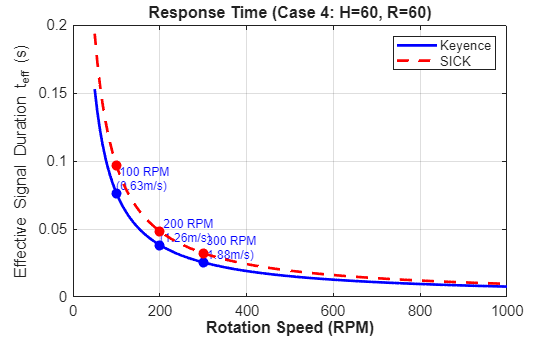


% Tính toán thời gian
r_m = R / 1000;
v_theory = (2 * pi * rpm_range / 60) * r_m; % Vận tốc dài tương ứng dải RPM

% Các mốc kiểm tra chẵn theo RPM
RPM_marks = [100, 200, 300];
V_marks = (2 * pi * RPM_marks / 60) * r_m;

% Vẽ Keyence (Nét liền màu xanh dương)
if S_eff_k > 0
    t_theory_k = (S_eff_k/1000) ./ v_theory; 
    plot(rpm_range, t_theory_k, '-b', 'LineWidth', 2, 'DisplayName', 'Keyence');
    
    % Chấm điểm 100, 200, 300 RPM
    t_marks_k = (S_eff_k/1000) ./ V_marks;
    plot(RPM_marks, t_marks_k, 'ob', 'MarkerSize', 7, 'MarkerFaceColor', 'b', 'HandleVisibility', 'off');
    
    for k = 1:length(RPM_marks)
        text(RPM_marks(k), t_marks_k(k), sprintf(' %d RPM\n(%.2fm/s)', RPM_marks(k), V_marks(k)), 'VerticalAlignment', 'bottom', 'Color', 'b', 'FontSize', 9);
    end
end

% Vẽ SICK (Nét đứt màu đỏ)
if S_eff_s > 0
    t_theory_s = (S_eff_s/1000) ./ v_theory; 
    plot(rpm_range, t_theory_s, '--r', 'LineWidth', 2, 'DisplayName', 'SICK');
    
    % Chấm điểm 100, 200, 300 RPM
    t_marks_s = (S_eff_s/1000) ./ V_marks;
    plot(RPM_marks, t_marks_s, 'or', 'MarkerSize', 7, 'MarkerFaceColor', 'r', 'HandleVisibility', 'off');
end

% 5. HOÀN THIỆN ĐỒ THỊ (Trục X chỉ hiển thị RPM)
xlim([0 1000]); % Giới hạn X để nhìn rõ vùng 100-300 RPM
set(gca, 'FontSize', 11, 'Box', 'on');

xlabel('Rotation Speed (RPM)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Effective Signal Duration t_{eff} (s)', 'FontSize', 12);
title(sprintf('Response Time (Case %d: H=%d, R=%d)', case_idx, H, R));
legend('Location', 'northeast');
hold off;


%% 6. XUẤT BẢNG SỐ LIỆU ĐỘNG HỌC CHO TRƯỜNG HỢP ĐÃ CHỌN
fprintf('\n============================================================================\n');

fprintf('       BẢNG TỔNG HỢP THỜI GIAN ĐÁP ỨNG HIỆU DỤNG (UNIT: SECONDS)\n');

       BẢNG TỔNG HỢP THỜI GIAN ĐÁP ỨNG HIỆU DỤNG (UNIT: SECONDS)


fprintf('============================================================================\n');


RPM_test = [100, 200, 300, 400, 1500, 1800, 3500, 4500];
V_test = (2 * pi * RPM_test / 60) * r_m;

fprintf('\nTRƯỜNG HỢP %d: [H = %d mm, R = %d mm]\n', case_idx, H, R);


TRƯỜNG HỢP 4: [H = 60 mm, R = 60 mm]


fprintf('S_raw: %.2f mm | S_eff_Keyence: %.2f mm | S_eff_SICK: %.2f mm\n', S_raw, S_eff_k, S_eff_s);

S_raw: 62.83 mm | S_eff_Keyence: 48.02 mm | S_eff_SICK: 60.83 mm


fprintf('----------------------------------------------------------------------------\n');

----------------------------------------------------------------------------


fprintf('  RPM  | V (m/s) |  t_Keyence (s)  |   t_SICK (s)   |    Đánh giá\n');

  RPM  | V (m/s) |  t_Keyence (s)  |   t_SICK (s)   |    Đánh giá


fprintf('----------------------------------------------------------------------------\n');

----------------------------------------------------------------------------



if S_eff_k <= 0
    fprintf('  [!] LỖI: Vết sáng Keyence lớn hơn cung mẫu, hệ thống bị nhiễu.\n');
    fprintf('----------------------------------------------------------------------------\n');
else
    for j = 1:length(RPM_test)
        rpm = RPM_test(j);
        v = V_test(j);
        
        t_k = (S_eff_k/1000) / v; 
        t_s = (S_eff_s/1000) / v; 
        
        status = 'OK (Cả 2)';
        if t_k < t_keyence && t_s >= t_sick
            status = 'Chỉ SICK OK';
        elseif t_s < t_sick
            status = 'FAIL Cả 2';
        end
        
        fprintf(' %4d  | %5.2f   |    %8.6f     |    %8.6f    |  %s\n', ...
            rpm, v, t_k, t_s, status);
    end
    fprintf('----------------------------------------------------------------------------\n');
end

  100  |  0.63   |    0.076425     |    0.096817    |  OK (Cả 2)
  200  |  1.26   |    0.038213     |    0.048408    |  OK (Cả 2)
  300  |  1.88   |    0.025475     |    0.032272    |  OK (Cả 2)
  400  |  2.51   |    0.019106     |    0.024204    |  OK (Cả 2)
 1500  |  9.42   |    0.005095     |    0.006454    |  OK (Cả 2)
 1800  | 11.31   |    0.004246     |    0.005379    |  OK (Cả 2)
 3500  | 21.99   |    0.002184     |    0.002766    |  OK (Cả 2)
 4500  | 28.27   |    0.001698     |    0.002151    |  OK (Cả 2)


----------------------------------------------------------------------------
